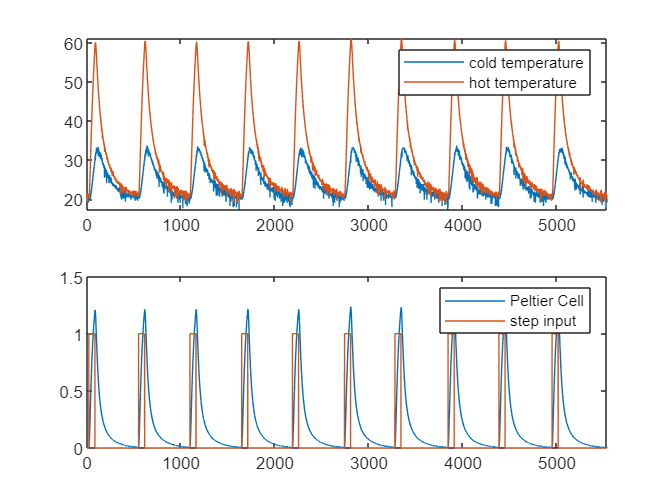

clear
load acquisizione_ventola_automatica_millis.mat %con BJT (caduta tensione 3V, estrusore alimentato a 9V invece di 12) e con ventola

cold_temperature=data(:,1);
hot_temperature=data(:,2);
step_input=data(:,4); %1 when thermoresistor on, 0 otherwise
v_peltier=data(:,3);

N=length(cold_temperature);

Ts=0.25; %4Hz -> 1 sample each 250 ms
t=0:0.25:0.25*(N-1); %tempo da 0 a N-1 (o da 1 a N) a passi di ts

figure;
subplot(2,1,1);
%plot(t,[smooth(cold_temperature),smooth(hot_temperature)]);
plot(t,[cold_temperature,hot_temperature]);
legend('cold temperature','hot temperature')
xlim([0,Ts*N])
subplot(2,1,2);
plot(t,[v_peltier,step_input]);
xlim([0,Ts*N])
legend('Peltier Cell','step input')


start_val=15360; %dividing identification set(first 7 cycles) and validation set (last 3)
%Note that this division in done only for V_in (step input) and V_out(Peltier voltage)

v_peltier_id=v_peltier(1:start_val-1);
v_peltier_val=v_peltier(start_val:end);

step_input_id=step_input(1:start_val-1);
step_input_val=step_input(start_val:end);

Comments on the system identification

0)Val is used as validation data (in basso a dx), id as working data (in alto a sx)

1) Arx2_1_15 (2 poles, 0 zeros (nb=nzeros+1=1 (of the exogenous input)), delay=15) has been chosen since very similar to the best model (that has na=nb=5 and delay=15 (samples) so much more parameters for almost the same performance). We used this type of model first since it allows to define different ranges for parameters and then provides the best among them.

2)ss2 is obtained with a state space of the second order since the best arx model has 2 poles and 0 zeros (so 2nd order, furthermore also this model tells that the best order is 2 with "pick the best value" option). While ss2delay is the same but with delay= 15 (since discrete time, so 15 samples). If continuos time we put (15-1)*ts=3.5seconds

3)All transfer function models have 2 poles and 0 zeros (as arx "told us"). We have no delay, 7.5 delay (useless, tried to see what happened) 3.5s and 3s delay (since 3.5 looks slightly too much), so a bit trial and error.

4)nlhw1,2,3,4 are different trials with the nonlinear method of Hammerstein wiener with denominator of order 2, numerator of order 0 and discrete delay=15 samples (the only difference is the number of breakpoints in the piecewise linear functions, we went for trial and error)

Note: 

1)We must have a pole in the origin since the extruder works as an integrator and we are including it in our model since we are giving an input (step) in voltage and measuring an output in voltage (ramp)

 2)Since the system works as an integrator, when we estimate models with delay, the system is able to place poles in the origin (one pole in the origin in present in the reality since it's an integrator). If we estimate models without any delay, the system tries to express both info of delay and integrator by moving the pole slightly on the left.